X=[14.90,14.40,13.56,15.55,13.97,16.33,14.37,13.46,15.51,14.69,13.41,14.24,15.65,14.54,13.55,13.15,14.32,15.04,13.27,14.60,13.83,13.93,14.11,14.15,15.48,15.96,14.46,13.87,13.67,15.30,13.95,16.08,18.25,14.93,15.37,14.38,15.56,13.92,14.23,12.80,13.16,13.89,14.24,13.90,12.82,13.20,13.89,13.50,13.44,16.13,14.68,15.27,13.35,13.62,16.16,16.46,13.83,14.13,15.68,15.22,12.59,12.94,13.09,16.54,14.61,14.63,14.17,13.34,16.74,16.30,13.74,15.02,14.96,15.87,16.03,12.87,14.32,14.48,14.57,14.43,12.61,14.52,15.29,12.07,14.58,11.74,14.97,14.31,12.94,12.82,14.13,14.48,12.25,14.39,15.08,12.87,14.25,15.12,15.35,12.27,14.43,13.85,13.16,16.77,14.47,14.89,14.95,14.55,12.80,15.26,13.32,14.92,13.44,13.48,12.81,15.01,13.19,14.68,14.44,14.89];
sortX = sort(X);

function [n, mx, dx] = FindEstimate(x)
    n = length(x);
    mx = sum(x) / length(x); % выборочное среднее
    dx = sum((x - mx).^2) / (length(x) - 1); % несмещённая оценка дисперсии
end

[n, mx, dx] = FindEstimate(X);
fprintf("Математическое ожидание X: %f.\n", mx);

Математическое ожидание X: 14.349167.


fprintf("Исправленная выборочная дисперсия X: %f.\n", dx);

Исправленная выборочная дисперсия X: 1.277621.


function mxLow = FindMxLow(x, gamma)
  [n, mx, dx] = FindEstimate(x);
  mxLow = mx - (sqrt(dx) * tinv((1 + gamma)/2, n-1) / sqrt(n));
end

function mxHigh = FindMxHigh(x, gamma)
  [n, mx, dx] = FindEstimate(x);
  mxHigh = mx + (sqrt(dx) * tinv((1 + gamma)/2, n-1) / sqrt(n));
end

function dxLow = FindDxLow(x, gamma)
  [n, ~, dx] = FindEstimate(x);
  dxLow = (n - 1) * dx / (chi2inv((1 + gamma) / 2, n-1));
end

function dxHigh = FindDxHigh(x, gamma)
  [n, ~, dx] = FindEstimate(x);
  dxHigh = (n - 1) * dx / (chi2inv((1 - gamma) / 2, n-1));
end

mxLow = FindMxLow(X, 0.9)

mxLow = 14.1781

mxHigh = FindMxHigh(X, 0.9)

mxHigh = 14.5202

dxLow = FindDxLow(X, 0.9)

dxLow = 1.0452

dxHigh = FindDxHigh(X, 0.9)

dxHigh = 1.6036

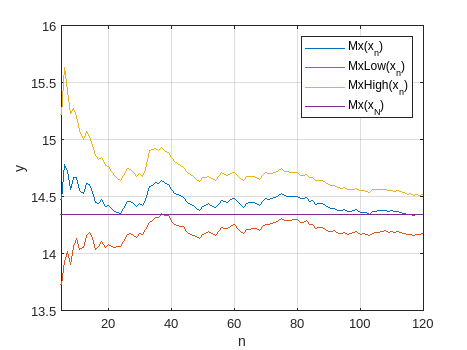

gamma = 0.9;

MxArr = zeros(1,n);
MxLowArr = zeros(1,n);
MxHighArr = zeros(1,n);
DxArr = zeros(1,n);
DxLowArr = zeros(1,n);
DxHighArr = zeros(1,n);
for i = 1:n
  xArr = X(1:i);
  [~, MxArr(i), DxArr(i)] = FindEstimate(xArr);
  MxLowArr(i) = FindMxLow(xArr, gamma);
  MxHighArr(i) = FindMxHigh(xArr, gamma);
  DxLowArr(i) = FindDxLow(xArr, gamma);
  DxHighArr(i) = FindDxHigh(xArr, gamma);
end

figure;
plot(1:n, [MxArr', MxLowArr', MxHighArr', mx*ones(n, 1)]);
grid on;
xlabel('n');
ylabel('y');
xlim([5,n]);
legend('Mx(x_n)', 'MxLow(x_n)', 'MxHigh(x_n)', 'Mx(x_N)');

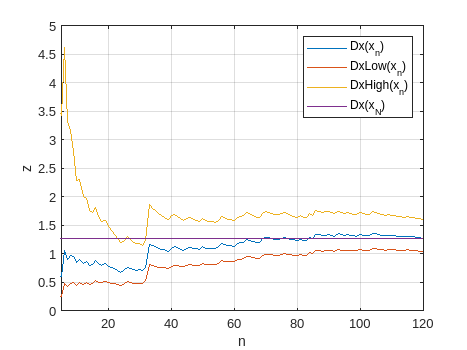


figure;
plot(1:n, [DxArr', DxLowArr', DxHighArr', dx*ones(n, 1)]);
grid on;
xlabel('n');
ylabel('z');
xlim([5,n]);

legend('Dx(x_n)', 'DxLow(x_n)', 'DxHigh(x_n)', 'Dx(x_N)');